% function XHAT = navsolLS(gECEF,prange_corr,sat_pos,GPStime,prnset)
if ~exist('clean')
    spoofingdetection
end
% if ~exist('brdcind')
    brdc = loadRINEXNavigation('G','data','brdc2580.12n');


>>> Merging files >>>
Output body:   RNX v2, "N" navigation message
Merging file:  brdc2580.12n --> body
------------------------------------------------------------------------
Files merged:  brdc2580.12n

>>> Loading content of merged file >>>
Loading nav RINEX: done!


% end

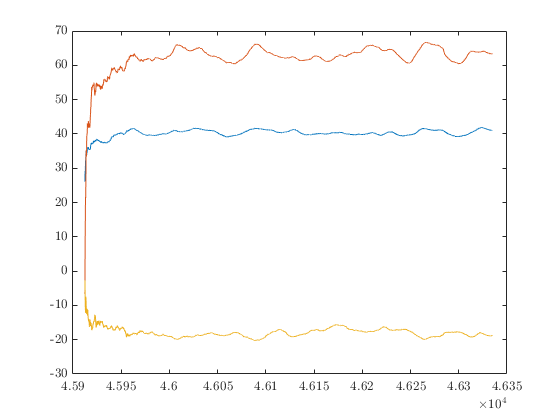

[~,brdcind] = ismember(prnnums,brdc.sat);
GPStime = ORT - dR/c; GPStime = mod(GPStime,24*3600);
GPStime2 = [ORT_weeksec(:,1), ORT_weeksec(:,2)-dR/c];
wgs = wgs84Ellipsoid;
UTECEF = [mean(x_cs),mean(y_cs),mean(z_cs)];
[UTGEO(1),UTGEO(2),UTGEO(3)] = ECEF2GEODETIC(UTECEF);
alpha = [0.1490D-07  0.2235D-07 -0.1192D-06 -0.1192D-06];
beta = [0.1085D+06  0.6554D+05 -0.1966D+06 -0.1311D+06];
timeind = 7;
for i = 1:length(prnnums)
    eph = brdc.eph{brdcind(i)}(:,timeind);
    a = eph(22);
    ecc = eph(20);
    TGD(i) = eph(37);
    svbias(i) = eph(12);
    [posT{i},aux{i}] = getSatPosGPS(GPStime2,eph);
    Ek = aux{i}(:,timeind);
%     posR = posT;
    posR{i} = rotPos(posT{i}(:,1),posT{i}(:,2),posT{i}(:,3),prange_cs(:,i)/c);
    LLA{i} = ecef2lla(posR{i},'WGS84');
    iono(:,i) = klobmodel(UTGEO(1),UTGEO(2),az_cs(:,i),el_cs(:,i),GPStime,alpha,beta);
    trop(:,i) = saastamoinen(.44,300,1011,UTGEO(1),UTGEO(2),UTGEO(3),az_cs(:,i),el_cs(:,i));
    trel(:,i) =  getSVRelativityClockCorrection('G',a,ecc,Ek);
end

n = length(prnnums);
prange_corr = prange_cs + svbias*c - iono - trop;
gECEF = [x_cs(1)-40;y_cs(1)-64;z_cs(1)+20];
sat_pos = posR; prnset = prnnums;
y = cell(length(GPStime),1);
H = cell(length(GPStime),1);
delR = cell(length(GPStime),1);
XHAT = cell(length(GPStime),1);
Xstar = cell(length(GPStime),1);

% iterative process for calculating navigation solution for all time steps
for p = 1:length(GPStime)
    Xstar{p} = [gECEF;1];
end
for i = 1:length(GPStime) % for each time step
    delta = 100;
    %%%% Iterated Part
    k = 1;
    while delta > 0.05
        if k > 1
            old = delR{i};
        end
        for j = 1:length(prnset)
            range_comp = norm(sat_pos{j}(i,:) - Xstar{i}(1:3)');
            prange_comp = range_comp+Xstar{i}(4);
            y{i}(j,:) = prange_corr(i,j) - prange_comp; %1
            H{i}(j,:) = [(Xstar{i}(1:3)'-sat_pos{j}(i,:))/range_comp,1]; %2
        end
        delR{i} = ((H{i}'*H{i})\H{i}'*y{i});
        XHAT{i} = Xstar{i}+delR{i};
        Xstar{i} = XHAT{i};
        estimate(i,:) = XHAT{i}';
        if k > 1
            delta = norm(delR{i}(1:3));
        end
        k = k+1;
    end
end
plot(GPStime,(estimate(:,1:3)-[x_cs,y_cs,z_cs]))